close("all"); clear; clc;

time = optvar("time","t","time","s",0,[],0);
position = optvar("position","x","position","m",0,1);
velocity = optvar("velocity","v","speed","m/s",0,0);

states = [
    position;
    velocity
    ];

force = optvar("force","F","force","N",[],[],-1,1);
controls = force;

x = ocpvars(time,states,controls);

w = ocpcost(x,@(x,u,t,p)1 + 0.*u(1,:));

mass = optparam("mass","m","kg",1,false);
plant = dyncon(x,@(x,u,t,p)slidingMass(x,u,p),mass);

C = ocpcon(x,plant);

prob = ocp(x,w,C);
disp(prob)

============================ Optimal Control Problem ===========================
                                    MINIMISE                                    


$$J=t_{f}$$

                                   SUBJECT TO                                   
=================================== Dynamics ===================================


$$\frac{\partial }{\partial t}x\left(t\right)=v\left(t\right)$$

$$\frac{\partial }{\partial t}v\left(t\right)=\frac{F\left(t\right)}{m}$$

============================== Control path bounds =============================


$$-1\leq F\left(t\right)$$

$$F\left(t\right)\leq 1$$

ns = 10;
M = ns + 1;
mesh = nlpmesh(linspace(0,1,M));

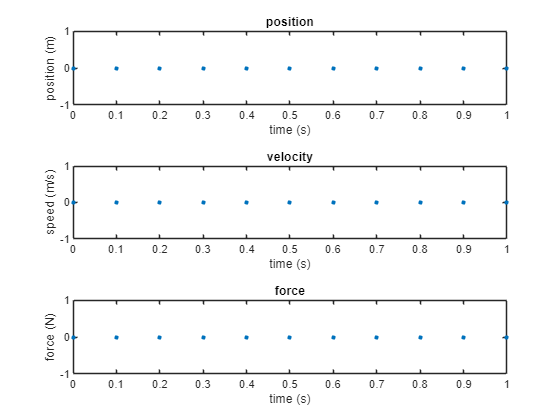

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


x0 = zeros(2,M);
u0 = zeros(1,M);
y0 = [x0;u0];
z = transcribevars(x,[1;y0(:)]);
z.plot(mesh,3,1)

% prog = prob.transcribe(mesh,x0,u0,0,10);

% opts = optimoptions( ...
%     "fmincon", ...
%     "MaxFunctionEvaluations",1E06 ...
%     );
% prog.solve(@trapezoidalCollocation,opts);

% t0 = prog.Variables.InitialTime;
% tf = prog.Variables.FinalTime;
% t = linspace(t0,tf,M);
% y = [prog.Variables.State;prog.Variables.Control];
% tiledlayout(3,1);
% for i = 1:3
%     nexttile;
%     plot(t,y(i,:));
%     xlim([t0,tf]);
% end